% Define parameters
m = 1000

m = 1000

b = 50 % damping

b = 50

f = 500 % nominal control force

f = 500

v = 10 % desired speed

v = 10

% Enter transfer function
s = tf('s') % define laplace variable s

s =
 
  s
 
Continuous-time transfer function.



P_cruise = 1/(m*s+b) % transfer function

P_cruise =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.



% Open loop step response - constant 500N force
u = 500 % 500N input force

u = 500

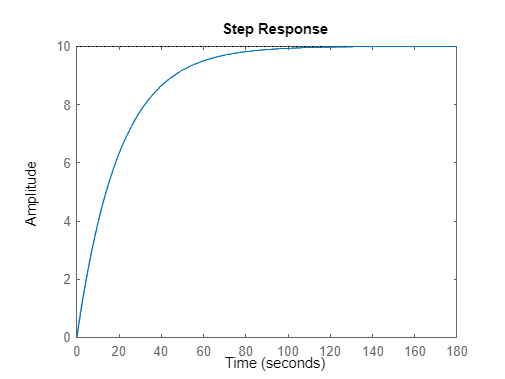

step(u*P_cruise)

S = stepinfo(P_cruise)

S = struct with fields:
         RiseTime: 43.9401
    TransientTime: 78.2415
     SettlingTime: 78.2415
      SettlingMin: 0.0181
      SettlingMax: 0.0200
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0200
         PeakTime: 210.9168


% Poles and zeros
pole1 = pole(P_cruise)

pole1 = -0.0500

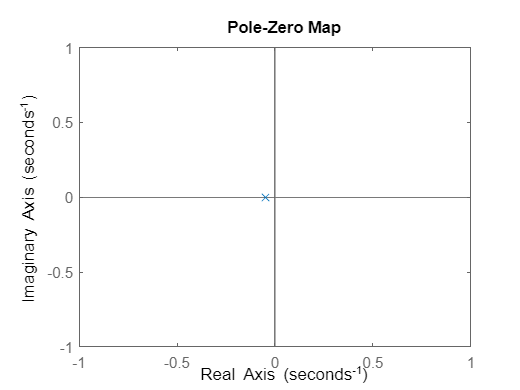

% Plot poles and zeros in s plane
pzmap(P_cruise)
axis([-1 1 -1 1])

% Define PID Controller
Kp = 1

Kp = 1

Ki = 1

Ki = 1

Kd = 1

Kd = 1


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



C = Kp + Ki/s +Kd*s

C =
 
  s^2 + s + 1
  -----------
       s
 
Continuous-time transfer function.



% You may use MATLABs inbuilt function as well
C = pid(Kp,Ki,Kd)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1, Ki = 1, Kd = 1
 
Continuous-time PID controller in parallel form.



% Proportional Control
% Note that this system is a closed feedback on the speed so
% our input r, is velocity
m = 1000

m = 1000

b = 50

b = 50

r = 10

r = 10


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



P_cruise = 1/(m*s + b)

P_cruise =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.




Kp= 5000 % subject to change

Kp = 5000

C = pid(Kp)

C =
 
  Kp = 5e+03
 
P-only controller.




T = feedback(C*P_cruise,1) % unity feedback

T =
 
      5000
  -------------
  1000 s + 5050
 
Continuous-time transfer function.



% Error passed through C, then through P_cruise
% T refers to the new transfer function with the feedback

t = [0:0.5:60] % array from 0 to 20 in steps of 0.1

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000


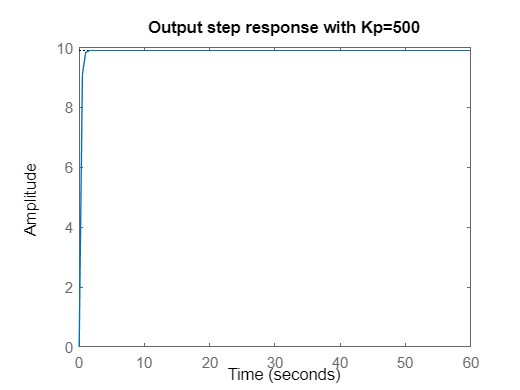

step(r*T,t)
title("Output step response with Kp=500")
axis([0 60 0 10]) % x and y (time and speed)

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.4351
    TransientTime: 0.7747
     SettlingTime: 0.7747
      SettlingMin: 0.8955
      SettlingMax: 0.9901
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9901
         PeakTime: 2.0883


pole(T)

ans = -5.0500

damp(T)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -5.05e+00     1.00e+00       5.05e+00         1.98e-01    


ans = struct with fields:
         RiseTime: 21.9701
    TransientTime: 39.1207
     SettlingTime: 39.1207
      SettlingMin: 0.4523
      SettlingMax: 0.5000
        Overshoot: 0
       Undershoot: 0
             Peak: 0.5000
         PeakTime: 105.4584


ans = -0.1000

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.00e-01     1.00e+00       1.00e-01         1.00e+01    


% Above system satisfies our requirements but is unrealistic due
% to power train limitataition
% Lets estimate required force, u for the above system
% u is now the output signal
Kp= 50

Kp = 50

C = pid(Kp)

C =
 
  Kp = 50
 
P-only controller.



T = feedback(C,P_cruise) %unity feedback now with force

T =
 
  50000 s + 2500
  --------------
   1000 s + 100
 
Continuous-time transfer function.



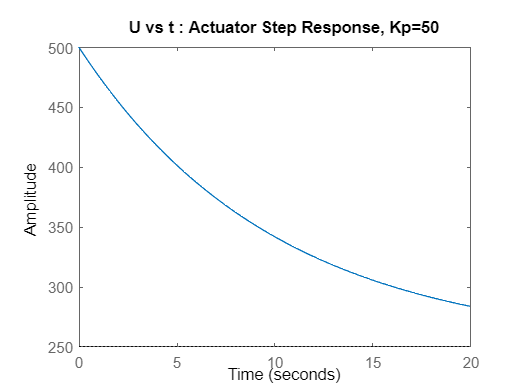

step(r*T,t)
title("U vs t : Actuator Step Response, Kp=")

stepinfo(T)

ans = struct with fields:
         RiseTime: 0
    TransientTime: 39.1207
     SettlingTime: 39.1207
      SettlingMin: 25.0007
      SettlingMax: 50
        Overshoot: 100
       Undershoot: 0
             Peak: 50
         PeakTime: 0


%  Now add integral controller
Kp = 800

Kp = 800

Ki = 40

Ki = 40

C = pid(Kp,Ki)

C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 800, Ki = 40
 
Continuous-time PI controller in parallel form.




T = feedback(C * P_cruise,1)

T =
 
       800 s + 40
  ---------------------
  1000 s^2 + 850 s + 40
 
Continuous-time transfer function.



t = [0:0.1:20]

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


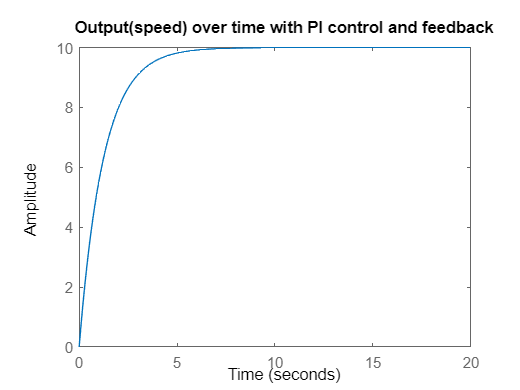

step(r*T,t)
title("Output(speed) over time with PI control and feedback")
axis([0 20 0 10])

stepinfo(T*r)

ans = struct with fields:
         RiseTime: 2.7463
    TransientTime: 4.8901
     SettlingTime: 4.8901
      SettlingMin: 9.0450
      SettlingMax: 9.9997
        Overshoot: 0
       Undershoot: 0
             Peak: 9.9997
         PeakTime: 13.1823


pole(T)

ans =    -0.8000
   -0.0500


damp(T)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -5.00e-02     1.00e+00       5.00e-02         2.00e+01    
 -8.00e-01     1.00e+00       8.00e-01         1.25e+00    


%  Now add derivative controller
Kp = 1

Kp = 1

Ki = 1

Ki = 1

Kd = 1

Kd = 1

C = pid(Kp,Ki, Kd)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1, Ki = 1, Kd = 1
 
Continuous-time PID controller in parallel form.




T = feedback(C * P_cruise,1)

T =
 
      s^2 + s + 1
  -------------------
  1001 s^2 + 51 s + 1
 
Continuous-time transfer function.



t = [0:2:200]

t =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


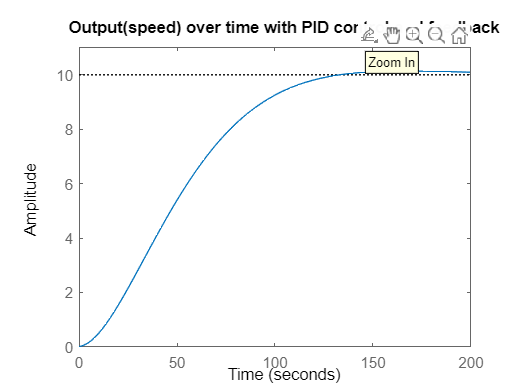

step(r*T,t)
title("Output(speed) over time with PID control and feedback")
axis([0 200 0 11])

stepinfo(T*r)

ans = struct with fields:
         RiseTime: 78.8382
    TransientTime: 119.3687
     SettlingTime: 119.3580
      SettlingMin: 9.0788
      SettlingMax: 10.1387
        Overshoot: 1.3867
       Undershoot: 0
             Peak: 10.1387
         PeakTime: 166.3135


pole(T)

ans =   -0.0255 + 0.0187i
  -0.0255 - 0.0187i


damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.55e-02 + 1.87e-02i     8.06e-01       3.16e-02         3.93e+01    
 -2.55e-02 - 1.87e-02i     8.06e-01       3.16e-02         3.93e+01    
